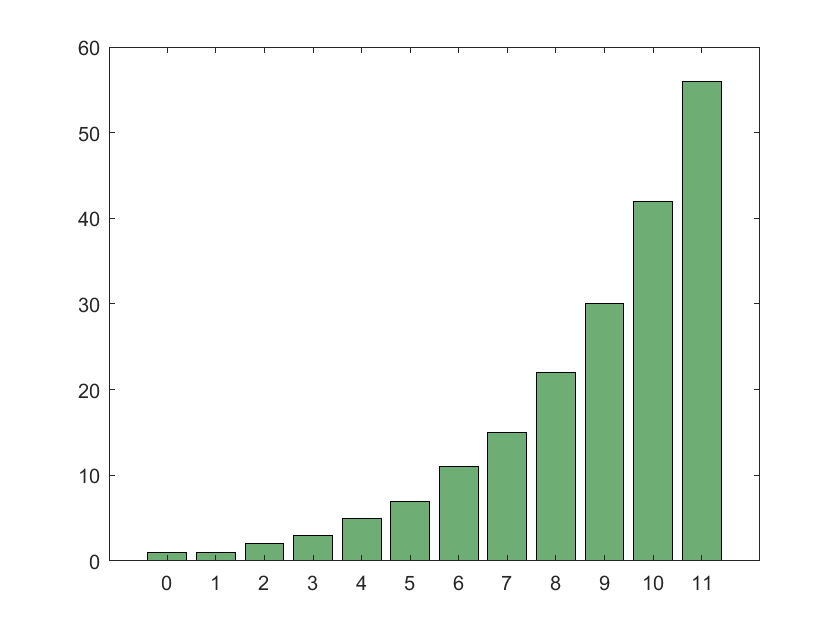

clear;clc;close
iterationNumber=11;
iterationVector = zeros(1,iterationNumber+1);
iterationVector(1)=1;
xAxisVector = 0:1:length(iterationVector)-1;
for iteration=2:1:length(iterationVector)
    tempIndexList = iteration:length(iterationVector);
    for tempValue = 1:1:length(tempIndexList)
        iterationVector(tempIndexList(tempValue)) = iterationVector(tempIndexList(tempValue)) + ...
                                                    iterationVector(tempValue);
         bar(xAxisVector,iterationVector,'FaceColor', [.43 .68 .45])
         pause(0.001)
    end
end